## 0. Initializing Variables and  Setting Functions

clear; clc;
fs = 1000;  %Number of samples per second
dur = 1;    %Signal duration in seconds
fm = 5;     %Multiplier for Frequency of Sine Wave in Hz
snr = 20;   % Signal to noise 
p_ratio =0.2;  % Poison ratio
function grapher(t, signal, color, mainTitle, xTityle,yTitle,new_legend)
    plot(t,signal, color,'LineWidth',1.5 );
    title(mainTitle);
    xlabel(xTityle);
    ylabel(yTitle);
    legend(new_legend);
    grid on;
end


function cSum = getChkSum(signal) % Get signal's integrity value
    cSum = sum(signal);  
end

## 1: Generation of Clean Wireless Signal

The first section involves generating a simple wireless signal to simulate a real world wireless situation. The signal created is a 5 Hz frequency sine wave representing the communication signal. 

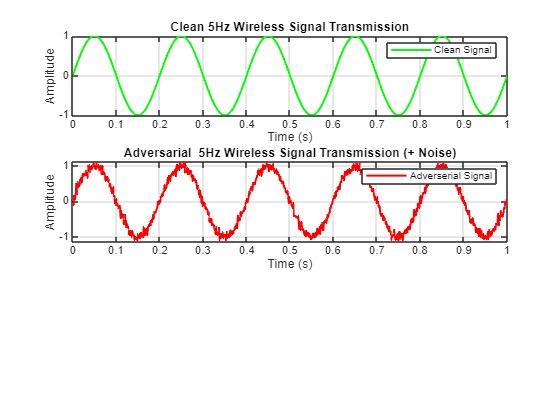

% Generate Clean Signal
t = linspace(0, dur, fs);  % Time range for signal (0 to 1 sec)
clean_signal = sin(2 * pi * fm * t);  % Generate main sine wave

adverserial_signal = awgn(clean_signal, snr, 'measured');


subplot(3,1,1);
grapher(t,clean_signal, 'g', 'Clean 5Hz Wireless Signal Transmission', 'Time (s)' , 'Amplitude', 'Clean Signal');

subplot(3,1,2);
grapher(t, adverserial_signal,'r' , 'Adversarial  5Hz Wireless Signal Transmission (+ Noise)','Time (s)', 'Amplitude', 'Adverserial Signal');

## 2. Checksum calculation 

clean_cSum = getChkSum(clean_signal);  % Checksum of clean signal
fprintf('Checksum of Clean Signal: %.2f\n', clean_cSum);

Checksum of Clean Signal: 0.00



% Calculate and display checksum for adversarial signal
adversarial_cSum = getChkSum(adverserial_signal);  % Calculate checksum
fprintf('Checksum of Adversarial Signal: %.2f\n', adversarial_cSum);

Checksum of Adversarial Signal: -2.31


## 3. Training the Machine Learning Classification Model

This section trains a Neural Network model to distinguish between clean and adversarial signals, being trained on the first modules’ signal datasets evaluating the model's ability to detect adversarial noise.

% Combine signals and create labels
combined_signal = [clean_signal, adverserial_signal];  % Combine signals into one row vector
labels = [ones(1, length(clean_signal)), zeros(1, length(adverserial_signal))];  % 1 = clean, 0 = adversarial

% Reshape data to match signal inputs
combined_signal = reshape(combined_signal, 1, []);  % Reshape to row vector
labels = reshape(labels, 1, []); 

nn = feedforwardnet([20, 15, 10]);  % Neural network with 3 hidden layers: 20, 15, and 10 neurons respectively
nn.trainParam.epochs = 1000;  % Increase the number of training epochs
nn.trainParam.lr = 0.01;  % Set learning rate
% Training network with given signal data for adverserial classification 
nn = train(nn, combined_signal, labels);

## 4. Adverserial Attack Detection

This section aims to predict added noise to wireless signals using the previously generated Neural Network Model.

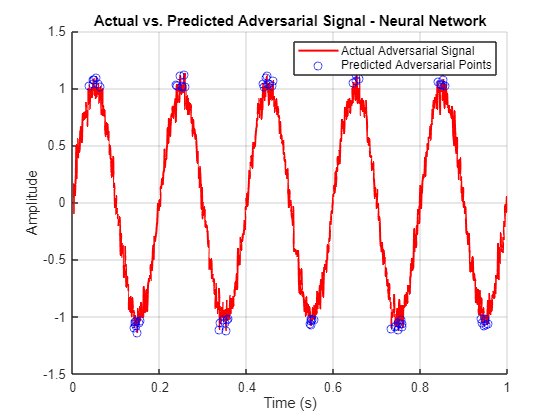

% Predict labels for signals
cp = nn(clean_signal);
adp = nn(adverserial_signal);

% Convert predictions to binary labels
pred_l_clean = cp > 0.35;  % Thresholding clean signal predictions
pred_l_adv = adp > 0.35;   % Thresholding adversarial signal predictions

% Create true labels
true_l_clean = ones(1, length(t));  % True labels for clean signal = 1
true_l_adv = zeros(1, length(t));   % True labels for adversarial signal =  0

% Combine predicted and true labels for both signals
pred_l = [pred_l_clean, pred_l_adv];
true_labels = [true_l_clean, true_l_adv];

% Calculate Precision, Recall, and F1 Score
TP = sum(pred_l == 1 & true_labels == 1);  % True positive
FP = sum(pred_l == 1 & true_labels == 0);  % False positives 
FN = sum(pred_l == 0 & true_labels == 1);  % False negatives

precision = TP / (TP + FP + eps);  % Adding eps to avoid division by zero
recall = TP / (TP + FN + eps);
f1_score = 2 * (precision * recall) / (precision + recall + eps);
figure;
hold on;
plot(t, adverserial_signal, 'r' ,'LineWidth', 1.5);  % Plot actual adversarial signal
plot(t(pred_l_adv == 0),adverserial_signal(pred_l_adv == 0), 'bo');  % Highlight points detected as adversarial
hold off;

% Label the plot
xlabel('Time (s)') ;
ylabel('Amplitude');
title('Actual vs. Predicted Adversarial Signal - Neural Network');
legend('Actual Adversarial Signal', 'Predicted Adversarial Points') ;
grid on;

fprintf('Adversarial Attack Detection - Precision: %.2f%%\n',precision * 100);

Adversarial Attack Detection - Precision: 51.81%


fprintf('Adversarial Attack Detection - Recall: %.2f%%\n', recall *100);

Adversarial Attack Detection - Recall: 100.00%


fprintf('Adversarial Attack Detection - F1 Score: %.2f%%\n',f1_score * 100)

Adversarial Attack Detection - F1 Score: 68.26%


## 5. Data Poisoning Attack

In this module, we assess the models’ resistance to data poisoning attack, this is accomplished by changing the value of clean signal labels to emulate the effects of data poisoning. The code intentionally poisons 20% of the dataset, flipping bits from 1 to 0 and retraining the support vector machine model based on the poisoned dataset

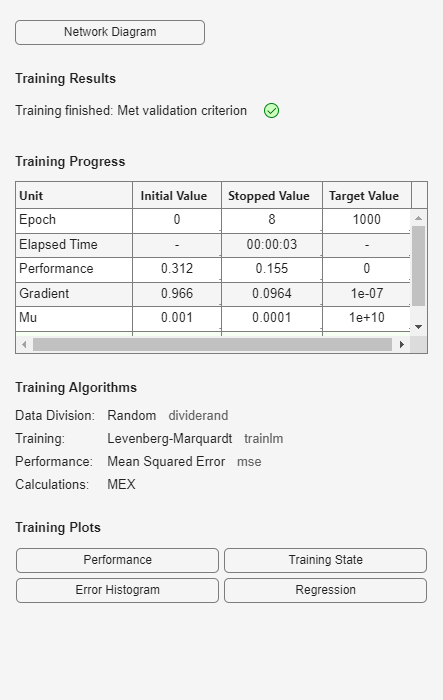


p_samples = round(fs *p_ratio);  % No. of poisoned samples
p_rand = randperm(fs, p_samples);  % Randomly choose samples to poison

p_labels = ones(1, length(t));  
p_labels(p_rand) =0;  % Change selected samples to 0 to poison the dataset

% Train the neural network on the poisoned dataset
nn_poisoned = feedforwardnet([20, 15, 10]);  % Complex neural network for poisoned dataset
nn_poisoned.trainParam.epochs =1000;
nn_poisoned = train(nn_poisoned,clean_signal,p_labels);



predictions = nn_poisoned(clean_signal); %Predict the poisoned dataset
predictions = round(predictions);  % Binarize results


accuracy = sum(predictions == p_labels) / length(t) *100; % Calculate model accuracy with poisoned data
fprintf('Model accuracy with poisoned dataset: %.2f%%\n',accuracy);

Model accuracy with poisoned dataset: 80.00%


poisoned_cSum = getChkSum(p_labels);  % Calculate checksum
fprintf('Checksum of Poisoned Labels: %.2f\n', poisoned_cSum);

Checksum of Poisoned Labels: 800.00


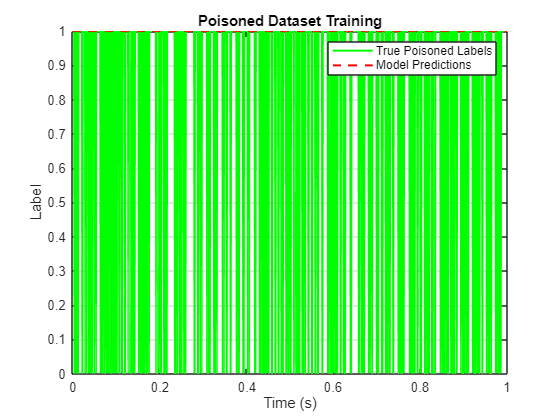


% Plot Poisoned Data with Model Predictions
figure;
plot(t, p_labels, 'g', 'LineWidth', 1.5);
hold on;
plot(t, predictions, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Label');
legend('True Poisoned Labels', 'Model Predictions');
title('Poisoned Dataset Training');
grid on;